# **Project One: **`Data Flow Modeling Using Matrix Theory`

## `Applied Linear Algebra`  |  *Student Name: *`Ryan Hatch`*  |  Date: *`10/4/24`

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>

# **Problem 1**

## **Develop a system of linear equations for the network **by writing an equation for each router `(A, B, C, D, and E)`. 

## Make sure to write your final answer as `A``x``=``b` where `A` is the `5x5` coefficient matrix, `x` is the `5x1` vector of unknowns, and `b` is a `5x1` vector of constants.

### Solution - Define the data rates between routers:

`x1: From Router A to Router B`

`x2: From Router A to Router E`

`x3: From Router B to Receiver`

`x4: From Router E to Router D`

`x5: From Router C to Router D`

**The system of equations based on inputs and outputs for each router is:**

1. `Router A: x1 + x2 = 100`

2. `Router B: x1 = x3`

3. `Router C: x5 = 50`

4. `Router D: x4 + x5 = 120`

5. `Router E: x2 = x4`

**Defining the matrix A, vector x, and vector b:**

`A = [1  1  0  0  0;    -1  0  1  0  0;     0  0  0  0  1;     0  0  0  1  1;     0 -1  0  1  0];`

`x = ['x1'; 'x2'; 'x3'; 'x4'; 'x5'];`

`b = [100; 0; 50; 120; 0];`

**Code to display the matrix and constant vector:**

% Defining the coefficient matrix A and vector b for the system Ax = b
A = [1  1  0  0  0;  % Equation for Router A: x1 + x2 = 100
    -1  0  1  0  0;  % Equation for Router B: x1 = x3
     0  0  0  0  1;  % Equation for Router C: x5 = 50
     0  0  0  1  1;  % Equation for Router D: x4 + x5 = 120
     0 -1  0  1  0]; % Equation for Router E: x2 = x4

b = [100;  % Input to Router A
      0;   % Output from Router B to Receiver
      50;  % Input to Router C
      120; % Output from Router D to Receiver
      0];  % Output from Router E to Router D

% Display the coefficient matrix and constant vector
disp('Coefficient matrix A:');

Coefficient matrix A:


disp(A);

     1     1     0     0     0
    -1     0     1     0     0
     0     0     0     0     1
     0     0     0     1     1
     0    -1     0     1     0



disp('Constant vector b:');

Constant vector b:


disp(b);

   100
     0
    50
   120
     0



%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>

# **Problem 2**

Use MATLAB to construct the augmented matrix [A **b**] and then perform row reduction using the rref() function. Write out your **reduced matrix and identify the free and basic variables of the system**.

### Solution:

% Define the coefficient matrix A
A = [1,  1,  0,  0,  0;
    -1,  0,  1,  0,  0;
     0,  0,  0,  0,  1;
     0,  0,  0,  1,  1;
     0, -1,  0,  1,  0];

% Define the constants vector b
b = [100; 0; 50; 120; 0];

% Construct the augmented matrix [A | b]
AugmentedMatrix = [A b];

% Perform row reduction using rref()
ReducedMatrix = rref(AugmentedMatrix);

% Display the reduced matrix
disp('Reduced Augmented Matrix:');

Reduced Augmented Matrix:


disp(ReducedMatrix);

     1     0     0     0     0    30
     0     1     0     0     0    70
     0     0     1     0     0    30
     0     0     0     1     0    70
     0     0     0     0     1    50



**Reduced Augmented Matrix:**

1 0 0 0 0 30

0 1 0 0 0 70

0 0 1 0 0 30

0 0 0 1 0 70

0 0 0 0 1 50

**Identification of Variables: ***All variables x1, x2, x3, x4, x5 are basic variables.* 

There are also no free variables and the system has a unique solution.

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>

# **Problem 3**

Use MATLAB to **compute the LU decomposition of A**, i.e., find A = LU. For this decomposition, find the transformed set of equations L**y** = **b**, where **y** = U**x**. Solve the system of equations L**y** = **b** for the unknown vector **y**.

### Solution:

% Perform LU decomposition
[L, U] = lu(A);

% Display L and U matrices
disp('L matrix:');

L matrix:


disp(L);

     1     0     0     0     0
    -1     1     0     0     0
     0     0     0     0     1
     0     0     0     1     0
     0    -1     1     0     0



disp('U matrix:');

U matrix:


disp(U);

     1     1     0     0     0
     0     1     1     0     0
     0     0     1     1     0
     0     0     0     1     1
     0     0     0     0     1




% Solve L * y = b for y
y = L \ b;

% Display the vector y
disp('Solution vector y:');

Solution vector y:


disp(y);

   100
   100
   100
   120
    50



The `lu()` function solves for the `LU` decomposition of `matrix A.`

**L** is a lower triangular matrix, and **U** is an upper triangular matrix.

I solved `Ly = b` using forward substitution.

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>

# **Problem 4**

**Compute the inverse **of U using the inv() function using MATLAB.

### Solution:

% Compute the inverse of U
U_inv = inv(U);

% Display the inverse of U
disp('Inverse of U:');

Inverse of U:


disp(U_inv);

     1    -1     1    -1     1
     0     1    -1     1    -1
     0     0     1    -1     1
     0     0     0     1    -1
     0     0     0     0     1



The `inv()` function computes the inverse of a matrix.

Finding out the solution to `U^-1` helped me to find `x` again in the future.

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>

# **Problem 5**

**Compute the solution to the original system of equations **by transforming **y **into **x**, i.e., compute **x** = inv(U)**y**.

### Solution:

% Compute the solution vector x
x = U_inv * y;

% Display the solution vector x
disp('Solution vector x:');

Solution vector x:


disp(x);

    30
    70
    30
    70
    50



Multiplying `U^-1` and `y` gave me the solution `x`.

This technically solves the original system `Ax = b`.

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>

# **Problem 6**

**Check answer for **$x_{1}$ **using Cramer’s Rule.** Use MATLAB to compute the required determinants using the det() function. 

### Solution:

% Compute the determinant of A
detA = det(A);

% Replace the first column of A with b to form A1
A1 = A;
A1(:,1) = b;

% Compute the determinant of A1
detA1 = det(A1);

% Compute x1 using Cramer's Rule
x1 = detA1 / detA;

% Display the computed x1
disp('x1 computed using Cramer''s Rule:');

x1 computed using Cramer's Rule:


disp(x1);

   30.0000



**Cramer's Rule:** `xi = det(Ai) / det(A) - ` where `Ai` is `A` with its `i-th` column replaced by `b.`

I solved `det(A)` and `det(A1)` in order to find `x1.`

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>

# **Problem 7**

#### Solution for the system of equations in the third column so it can be easily compared to the maximum capacity in the second column. 

#### In the fourth column of the table, provide recommendations for how the network should be modified based on your network throughput analysis findings. The modification options can be `No Change`, `Remove Link`, or `Upgrade Link.` In the final column, explain how you arrived at your recommendation.

### Solution:

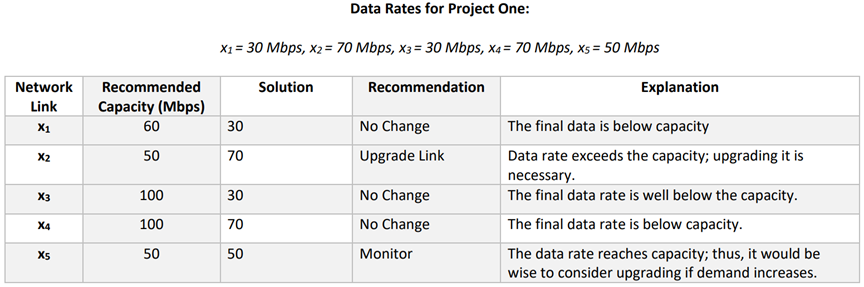

*By modeling the network as a system of linear equations and then applying matrix techniques to solve them, I was able to find out what the data rates for each link in the network are. Using the tools from MATLAB I was able to perform tasks like row reduction, LU decomposition, and I also applied Cramer's Rule to verify the solutions. In the final result, I then gave recommendations that were based on the data rates to make sure that the network operates at the most optimal rate without over working or exceeding any link capacities.*

%<><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><><>